ans = 0.4207

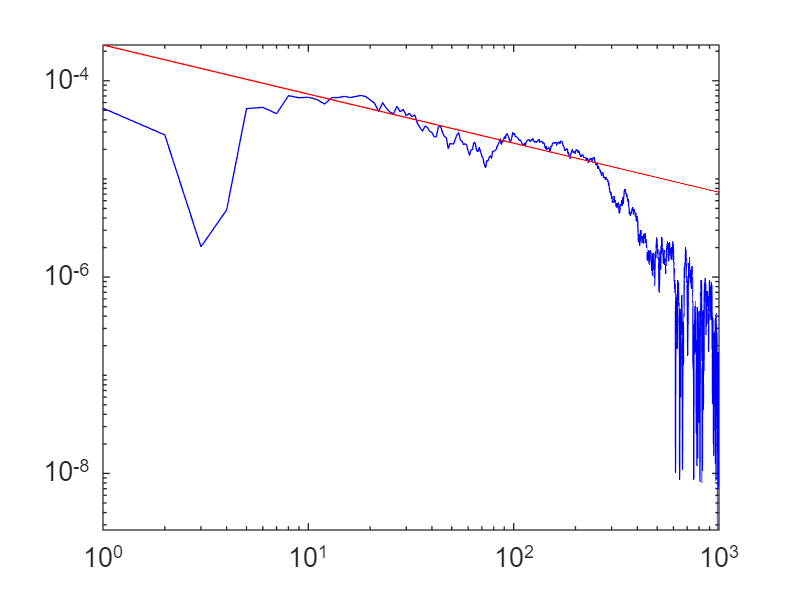

% Set N to a power of two such that we can easily generate the Brownian
% Bridges and let T be the final time
d=1;
N=2^14;
M=1000;

sigma = 0.4;
r = 0;
T = 1;
K = 100;
X_0 = 100;

C = 2; % MC = 1, QMC = 2, both = 3;

avg = 0;

if C == 1
    evs = zeros(M,1);
    variances = zeros(M,1);
    for samples=1:M
        R = randn(N,1);
        A = eye(d,d);
        for i = 1:d
            A(1,i) = 1/sqrt(d);
        end

        A_inv = A^(-1);

        Z_1 = zeros(d,1);
        for i = 1:d
            Z_1(i) = R(1,i);
        end
    
        B = bridge(N,R,1);

        eps = 10;
        Tol = 10e-9;
        
        Y = A*Z_1;
        y = Y(1);
        tmp = Y;
        k = 1;
        
        %F(tmp,B,N,sigma,T,A_inv)
        %prod(F(tmp,B,N,sigma,T,A_inv))
        %sum(1/F(tmp,B,N,sigma,T,A_inv))
        %sum(1./F(tmp,B,N,sigma,T,A_inv))
        
        while eps > Tol
           y = y-(prod(F(tmp,B,N,sigma,T,A_inv))-K/X_0)/((sigma*sqrt(T)/N)*prod(F(tmp,B,N,sigma,T,A_inv))*sum(1./F(tmp,B,N,sigma,T,A_inv)));
           tmp(1) = y;
           eps = abs(X_0*prod(F(tmp,B,N,sigma,T,A_inv))-K);
           k = k + 1;
        end
        
        l = 16;
        
        [x,w] = GaussLaguerre(l,0);
        
        laguerreleft = zeros(l,1);
        laguerreright = zeros(l,1);
        
        for i=1:l
            laguerreleft(i)=w(i)*G(y-x(i), B, N, sigma, T, X_0, K, A_inv)*normpdf(y-x(i))*exp(x(i));
            laguerreright(i)=w(i)*G(y+x(i), B, N, sigma, T, X_0, K, A_inv)*normpdf(y+x(i))*exp(x(i));
        end
        
        laguerretotal = sum(laguerreleft)+sum(laguerreright);
    
        avg = avg + laguerretotal;
        evs(samples) = avg/samples;
        variances(samples) = laguerretotal;
    end
    refsolution = avg/M;
    variance = var(variances);
    bound = zeros(M,1);
    for i=1:M
        bound(i) = 1.96*sqrt(variance)/sqrt(i);
    end
    avg/M
    loglog(1:M, abs(evs-refsolution), 'blue', 1:M, bound, 'red');
end

if C == 2
    evs = zeros(M,1);
    variances = zeros(M,1);
    for samples=1:M
        P = sobolset(d);
        P = scramble(P,'MatousekAffineOwen');
        Q = net(P,N+1);
        R = zeros(N-1,d);
        R = norminv(Q);
        A = eye(d,d);
        for i = 1:d
            A(1,i) = 1/sqrt(d);
        end

        A_inv = A^(-1);

        Z_1 = zeros(d,1);
        for i = 1:d
            Z_1(i) = R(1,i);
        end
    
        B = bridge(N,R,1);

        eps = 10;
        Tol = 10e-9;
        
        Y = A*Z_1;
        y = Y(1);
        tmp = Y;
        k = 1;
        
        %F(tmp,B,N,sigma,T,A_inv)
        %prod(F(tmp,B,N,sigma,T,A_inv))
        %sum(1/F(tmp,B,N,sigma,T,A_inv))
        %sum(1./F(tmp,B,N,sigma,T,A_inv))
        
        while eps > Tol
           y = y-(prod(F(tmp,B,N,sigma,T,A_inv))-K/X_0)/((sigma*sqrt(T)/N)*prod(F(tmp,B,N,sigma,T,A_inv))*sum(1./F(tmp,B,N,sigma,T,A_inv)));
           tmp(1) = y;
           eps = abs(X_0*prod(F(tmp,B,N,sigma,T,A_inv))-K);
           k = k + 1;
        end
        
        l = 16;
        
        [x,w] = GaussLaguerre(l,0);
        
        laguerreleft = zeros(l,1);
        laguerreright = zeros(l,1);
        
        for i=1:l
            laguerreleft(i)=w(i)*G(y-x(i), B, N, sigma, T, X_0, K, A_inv)*normpdf(y-x(i))*exp(x(i));
            laguerreright(i)=w(i)*G(y+x(i), B, N, sigma, T, X_0, K, A_inv)*normpdf(y+x(i))*exp(x(i));
        end
        
        laguerretotal = sum(laguerreleft)+sum(laguerreright);
    
        avg = avg + laguerretotal;
        evs(samples) = avg/samples;
        variances(samples) = laguerretotal;
    end
    refsolution = avg/M;
    variance = var(variances);
    bound = zeros(M,1);
    for i=1:M
        bound(i) = 1.96*sqrt(variance)/sqrt(i);
    end
    avg/M
    loglog(1:M, abs(evs-refsolution), 'blue', 1:M, bound, 'red');
end

function path = bridge(N,R,dimension)
    h = N+1;
    path = zeros(N+1, 1);
    %path(N+1) = sqrt(T)*R(1,dimension);
    path(N+1) = 0;
    for k = 1:log2(N)
        h = (h-1)/2;
        for j = 1:2^(k-1)
            path((2*j-1)*h+1) = 1/2*(path(2*(j-1)*h + 1) + path(2*j*h + 1)) + sqrt(1/2*(h/(N+1)))*R(j+2^(k-1)-1,dimension);
        end
        h = h + 1;
    end
end

% Since we have only one dimension, the term sum_i=2^d ... is empty
function factors = F(Y, B, N, sigma, T, A_inv)
    factors = zeros(N,1);
    for n = 1:N
        factors(n) = 1 + sigma*sqrt(T)/N*A_inv(1,1)*Y(1) + sigma*(B(n+1)-B(n));
    end
end

function finalvalG = G(y, B, N, sigma, T, X_0, K, A_inv)
    factors = zeros(N,1);
    for n = 1:N
        factors(n) = 1 + sigma*sqrt(T)/N*y + sigma*(B(n+1)-B(n));
    end
    product = X_0*prod(factors);
    finalvalG = 0;
    if product >= K
        finalvalG = 1;
    end
end